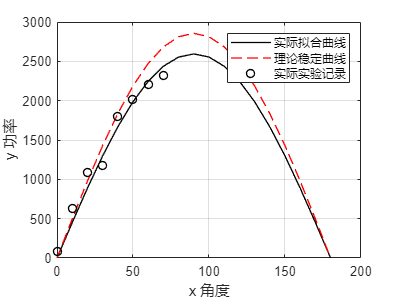

x=[0,10,20,30,40,50,60,70];
y=[87,625,1087,1175,1800,2018,2206,2318];
xd=x*pi/180;
z=[0:10:180];
zf=2594*sin(z*1*pi/180);
zf2=2856*sin(z*pi/180);
h=plot(z,zf,'k-',z,zf2,'r--',x,y,'ko',LineWidth=1);
legend( h, '实际拟合曲线', '理论稳定曲线', '实际实验记录','Location', 'NorthEast', 'Interpreter', 'none' );
xlabel( 'x 角度', 'Interpreter', 'none' );
ylabel( 'y 功率', 'Interpreter', 'none' );
grid on

function [fitresult, gof] = createFit(x, y)
%CREATEFIT(X,Y)
%  创建一个拟合。
%
%  要进行 '无标题拟合 1' 拟合的数据:
%      X 输入: x
%      Y 输出: y
%  输出:
%      fitresult: 表示拟合的拟合对象。
%      gof: 带有拟合优度信息的结构体。
%
%  另请参阅 FIT, CFIT, SFIT.

%  由 MATLAB 于 28-Oct-2022 22:10:57 自动生成


%% 拟合: '无标题拟合 1'。
[xData, yData] = prepareCurveData( x, y );

% 设置 fittype 和选项。
ft = fittype( 'sin1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf 0 -Inf];
opts.StartPoint = [2110.50108670771 0.0448798950512828 -0.478735204495488];

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );

% 绘制数据拟合图。
figure( 'Name', '无标题拟合 1' );
h = plot( fitresult, xData, yData );
legend( h, '实际数据记录', '实际拟合曲线', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( 'x', 'Interpreter', 'none' );
ylabel( 'y', 'Interpreter', 'none' );
grid on
end